## Problem 4.

Prob 3과 동일한 1차 시스템에 대하여 1차 참조모델을 추종하는 제어기를 설계하고자 한다. 추종하고자 하는 참조모델은 다음과 같다.


$$\dot{y}_m = -4y_m + 4r$$


clc; close all; clear all;

### a)

일차 시스템의 파라미터 초기 추정치를 다음과 같이 설정 했을 때 $(\hat{a}_0=1, \hat{b}_0=2)$, 참조모델을 추종하기 위하여 고려하는 제어 구조는 다음과 같다.


$$u = k_1 r - k_2 y$$


이때 참조모델을 추종하기 위한 초기 제어이득 $(k_{1_0}, k_{2_0})$을 구하라. 실제 시스템에 초기 제어이득 $(k_{1_0}, k_{2_0})$을 적용하여 제어기를 설계했을 때 단위 계단 입력에 대한 출력 $y$와 $u$의 시간 반응을 그래프로 나타내라

***sol)***

추종하고자 하는 참조 모델은 $\dot{y}_m = -4y_m + 4r$로, problem3과 동일한 1차 시스템을 고려하며 제어구조를 적용했을 때 $\dot{y} = \hat{a}_0 y + \hat{b}_0 (k_1r - k_2y)$와 같은 꼴로 나타낼 수 있다. 위 참조 모델을 추종하기 위한 $k_1$은 $2k_1 = 4$로 $2$이다. 그리고 $k_2$는 $\hat{a}_0 - \hat{b}_0k_2 = -4$로 $5/2$이다.


$$k_{1_0}=2, k_{2_0} = \frac52$$


이에 대한 $y$, $u$ 시간 반응 그래프를 나타내 보았다.

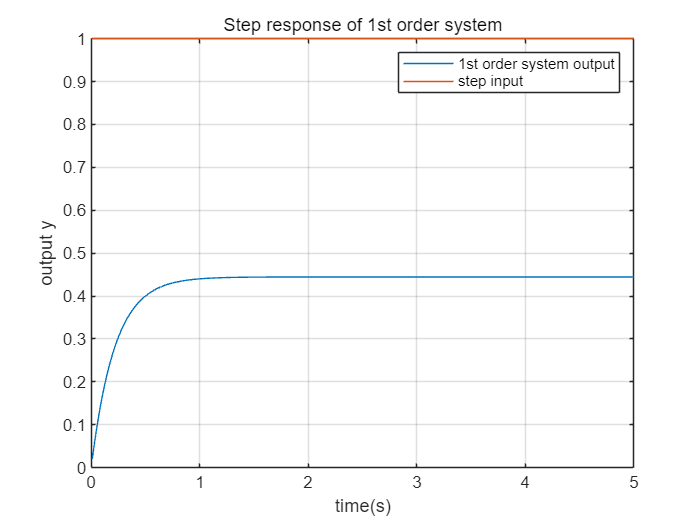

rng(0);
timestep = 0.01;
Time = 5;
time = linspace(0, Time, Time/timestep + 1);
real_theta = [-2, 1];
real_dot_y = 0;

y = 0;                          % y(t)
prev_y = 0;                     % y(t-1)
model_dot_y = 0;                % \dot{y}
r = 1;                          %%%% Unit step input %%%%
u = 0;                          % Initial input u
gain = [2, 5/2];                % Gain parameter
output_data = [];               % Output data

for k = 1 : length(time)
    if (k + 1 > length(time))
        break;
    end
    u = gain(1)*r - gain(2)*prev_y;
    varphi = [prev_y, u];                    
    real_dot_y = varphi*real_theta';    % dot_output from reference model
    y = prev_y + real_dot_y*timestep;   % Plant model output update
    output_data = [output_data, y];
    prev_y = y;
end

outputy = plot(time(2:end), output_data);
hold on; grid on;
stepinput = plot(time(2:end), ones([length(time(2:end)), 1]));
xlabel("time(s)"); ylabel("output y"); title("Step response of 1st order system");
legend([outputy, stepinput], {"1st order system output", "step input"});
hold off;

### b)

시스템 초기 제어이득을 기준으로 제어 파라미터를 변경하는 direct adaptive approach를 적용하여 $(k_1, k_2)$에 대한 적응규칙을 설계하여라. 적응규칙에 따른 적응제어기의 단위 계단 입력 에 대한 출력 $y$와 $u$의 시간반응을 그래프로 나타내고 a)의 결과와 비교하여라.

***sol)***

$e = r - y$이라고 했을 때, quadratic cost function $J=\frac12 e^2$이므로 MIT rule을 적용하기 위한 $\dot{\hat{\theta}} = -\gamma\frac{dJ}{d\theta}$이다. $-\gamma\frac{dJ}{d\theta} = -\gamma\frac{dJ}{de}\frac{de}{d\theta}$이므로 $\dot{\hat{\theta}} = -\gamma e$$\left\lbrack \begin{array}{c}
\frac{\partial \left(r-y_{\;} \right)}{\partial k_1 }\\
\frac{\partial \left(r-y_{\;} \right)}{\partial k_2 }
\end{array}\right\rbrack$이다. $\left\lbrack \begin{array}{c}
\frac{\partial \left(r-y_{\;} \right)}{\partial k_1 }\\
\frac{\partial \left(r-y_{\;} \right)}{\partial k_2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{b_{\;} }{s-a_{\;} +b_{\;} k_2 }R\left(s\right)\\
\frac{{-b}_{\;} }{s-a_{\;} +b_{\;} k_2 }Y\left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\textrm{be}}^{-\left(-a+{\textrm{bk}}_2 \right)T} r\\
-{\textrm{be}}^{-\left(-a+{\textrm{bk}}_2 \right)T} y
\end{array}\right\rbrack$ 

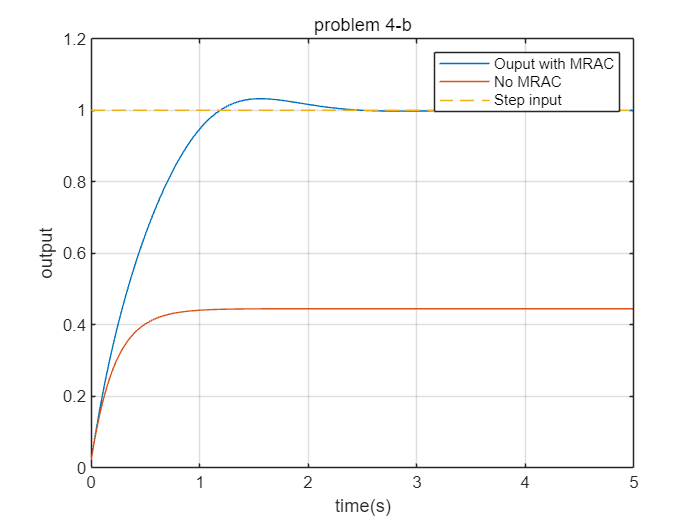

prev_output_data_a = output_data;
timestep = 0.01;
Time = 5;
time = linspace(0, Time, Time/timestep + 1);

real_theta = [-2, 1];           % Real Theta (plant parameters)
real_dot_y = 0;                 % Plant's derivative output (dot y)
gain = [2, 5/2];                % Initial adaptive gains
prev_gain = gain;               % Previous gains for update check
gain_data = [];                 % Gain data
y = 0;                          % Plant output y(t)
prev_y = 0;                     % Plant output y(t-1)
model_y = 0;                    % Reference model output y_m(t)
error = 0;                      % Initial error
r = 1;                          % Unit step input
u = 0;                          % Initial input u
update_param = [0; 0];

ref_model = [-4, 4];            % Reference model: dot y_m = -4y_m + 4r


varphi = zeros([1, 2]);         % Regression vector (phi)
error = 0;                      % Initial error
output_data = [];               % Data array for tracking outputs

gamma = 1.2;                     % Update parameter (learning rate)

% Simulation loop
for k = 1 : length(time)
    if (k + 1 > length(time))
        break;
    end
    
    u = gain(1)*r - gain(2)*y;
    varphi = [y, u];
    model_dot_y = varphi * ref_model';
    real_dot_y = varphi * real_theta';
    y = prev_y + real_dot_y * timestep;
    update_param = 4*exp(-4*timestep).*[r; -y];
    error = r - y;
    gain = prev_gain + timestep*(gamma*error).*update_param';
    % Update parameter rule based on MIT rule
    % theta_hat_dot = -gamma * (∂J/∂theta) = gamma * error * ∂y_m/∂theta
    
    output_data = [output_data, y];
    
    % Update previous output
    prev_y = y;
    prev_gain = gain;
end

b = plot(time(1:length(output_data)), output_data);
hold on; grid on;
a = plot(time(1:length(output_data)), prev_output_data_a);
step = plot(time(1:length(output_data)), ones([length(output_data)', 1]), '--');
legend([b, a, step], {"Ouput with MRAC", "No MRAC", "Step input"});
xlabel("time(s)"); ylabel("output"); title("problem 4-b");
hold off;

$\gamma = 1.2$로 MRAC를 적용한 제어기의 경우 MRAC를 고려하지 않은 제어기 a)보다 unit step input을 잘 추종하는 모습을 보여준다. 

### c)

$(k_{1_0}, k_{2_0})$는 그대로 두고 시스템 파라미터 를 변경하는 indirect adaptive approach를 적용하고자 한다. 이를 위한 $(\hat{a}, \hat{b})$에 대한 적응 규칙을 설계하여라. 적응규칙에 따른 적응제어기의 단위 계단 입력 에 대한 출력 $y$와 $u$ 의 시간반응을 그래프로 나타내고 a), b)의 결과와 비교하여라

***sol)***

Reference model $\hat{\theta}$의 update를 위해 MIT rule $\dot{\hat{\theta}} = -\gamma\frac{dJ}{d\hat{\theta}} = -\gamma\frac{dJ}{d\epsilon}\frac{d\epsilon}{d\hat{\theta}} = -\gamma e\frac{d\epsilon}{d\hat{\theta}}$을 이용한다. $\epsilon = z - \hat{z} = z - \varphi(y, u)^T \hat{\theta}$로 $z=\dot{y}$, $\hat{z} = \varphi(y, u)^T\hat{\theta}$이다. 

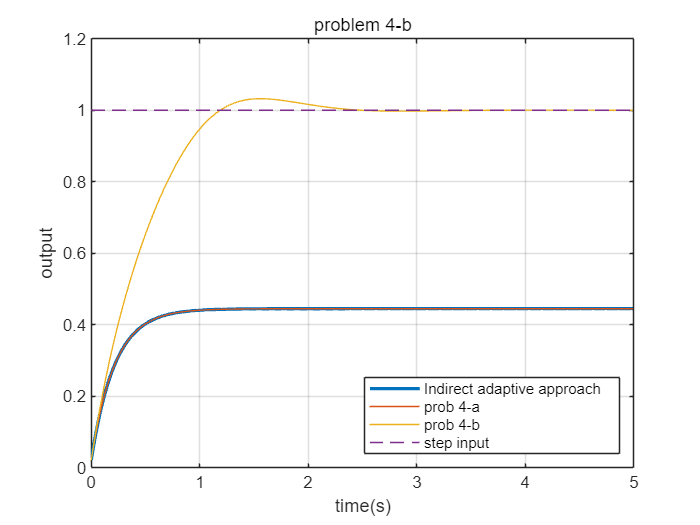

prev_output_data_b = output_data;
timestep = 0.01;
Time = 5;
time = linspace(0, Time, Time/timestep + 1);

real_theta = [-2, 1];           % Real Theta (plant parameters)
real_dot_y = 0;                 % Plant's derivative output (dot y)
gain = [2, 5/2];                % Initial adaptive gains
prev_gain = gain;               % Previous gains for update check
gain_data = [];                 % Gain data
y = 0;                          % Plant output y(t)
prev_y = 0;                     % Plant output y(t-1)
model_y = 0;                    % Reference model output y_m(t)
error = 0;                      % Initial error
r = 1;                          % Unit step input
u = 0;                          % Initial input u
hat_theta_data = [];            % Empty array for collecting data
update_param = [0; 0];

ref_model = [-4, 4];            % Reference model: dot y_m = -4y_m + 4r
prev_ref_model = ref_model;
dot_ref_model = [];
ref_model_data = [];

varphi = zeros([1, 2]);         % Regression vector (phi)
error = 0;                      % Initial error
output_data = [];               % Data array for tracking outputs

gamma = 1;                    % Update parameter (learning rate)

% Simulation loop
for k = 1 : length(time)
    if (k + 1 > length(time))
        break;
    end
    u = gain(1)*r - gain(2)*y;
    varphi = [y, r];
    varphi_real = [y, u];
    model_dot_y = varphi * ref_model';
    real_dot_y = varphi_real * real_theta';
    y = prev_y + real_dot_y * timestep;
    error = real_dot_y - model_dot_y;
    dot_ref_model = gamma*error*ref_model;
    ref_model = prev_ref_model + timestep*dot_ref_model;
    output_data = [output_data, y];
    ref_model_data = [ref_model_data, ref_model'];
    prev_y = y;
    prev_gain = gain;
end

Output = plot(time(1:length(output_data)), output_data, "LineWidth", 2);
hold on; grid on;
a = plot(time(1:length(output_data)), prev_output_data_a);
b = plot(time(1:length(output_data)), prev_output_data_b);
step = plot(time(1:length(output_data)), ones([length(output_data)', 1]), '--');
xlabel("time(s)"); ylabel("output"); title("problem 4-b");
legend([Output, a, b, step], {"Indirect adaptive approach", "prob 4-a", "prob 4-b", "step input"}, "Location", "southeast");
hold off;

$\gamma = 1$ 가정 하에서  indirective adaptive approach는 MRAC보다 step input에 대한 추종 성능이 떨어지는 모습을 확인할 수 있다. 정확히는 4-a의 시간반응 그래프와 동일한 것을 확인할 수 있다. 이는 indirect adaptive approach에서 plant는 변하지 않고 reference model만이 update 되고 있는데, controller의 gain을 변화시키지 않고서는 시스템의 특성을 바꾸지 못하기에 위와 같은 결과가 출력된 것을 확인할 수 있다.